# Implementation of Zhang's method

## Calibrate using Zhang procedure

In this script it is provided an implementation of Zhang's procedure to estimate perspective projection parameters $P$.

To estimatie it, matrix $K$ of intrinsic parameters and $R$, $t$ (extrinsic parameters, corresponding to rotation, and translation corresponding to the rigid transformation from the world reference frame to the camera reference frame) are computed for each image.

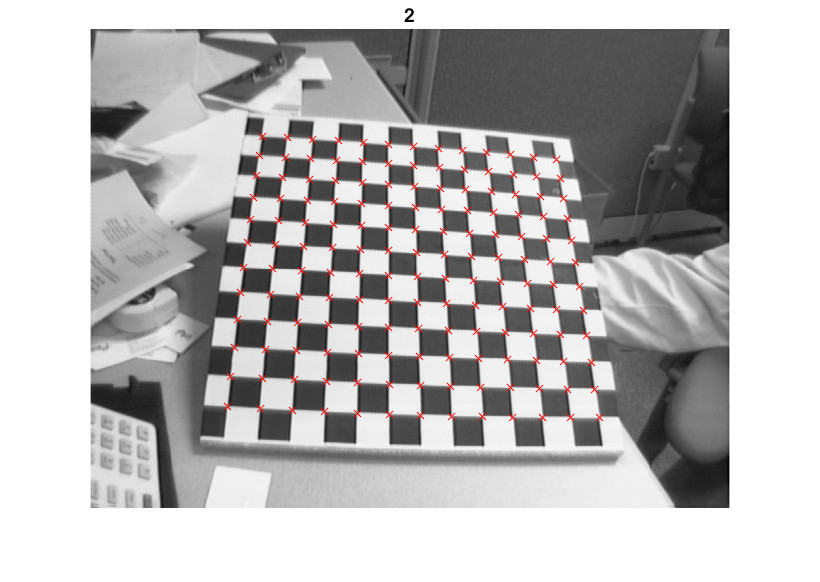

% load checkerboard images
clear imageData

folder = 'images/';
a = dir('images/*.tif');
n = numel(a); % find number of files in folder

imageData(n) = struct();

for i = 1:n
    imageFileName = fullfile('images',['image' num2str(i) '.tif']);
    imageData(i).I = imread(imageFileName); 
    % the flag 'PartialDections' is needed otherwise 
    % on few images it detects the wrong number of points
    imageData(i).XYpixel = detectCheckerboardPoints(imageData(i).I, ...
                            'PartialDetections', false);  
end

% show the detected points on an image of the dataset
figure

idx = 2; % here we choose the first one
imshow(imageData(idx).I, 'initialmagnification',200);
title(num2str(idx))
hold on
for j=1:size(imageData(idx).XYpixel,1)
    x = imageData(idx).XYpixel(j,1);
    y = imageData(idx).XYpixel(j,2);
    scatter(x,y, 'x', 'r')
end

 % it should be 12x13, the number of internal points of the checkerboard
fprintf('Points detected in image 2: %d', length(imageData(2).XYpixel))

Points detected in image 2: 156

The detected points are our 2D points in image reference frame $m' = [u\  v \  1]^T$.

Now we want to assign the corresponding coordinates in $mm$ with respect to world reference frame.

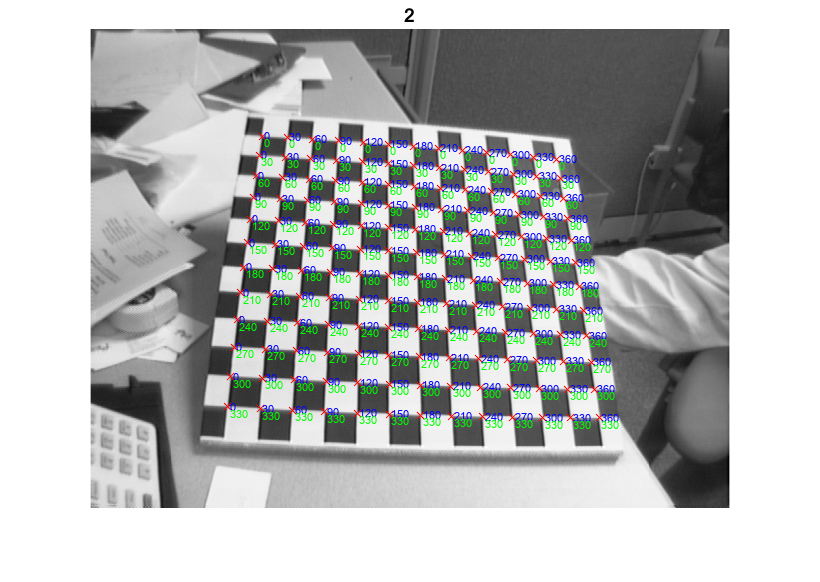

squaresize = 30; % mm
chessboardSize = [12,13];

for i=1:n
    XYpixel = imageData(i).XYpixel;

    clear Xmm Ymm
    for j=1:length(XYpixel)
        % this function based provides provides the row and 
        % column position of each point in a matrix of given
        % size (whose measures are read as n. row and n. column)
        [row,col] = ind2sub(chessboardSize,j);

        % corresponding coordinates for each point in millimiters
        Xmm = (col-1)*squaresize;
        Ymm = (row-1)*squaresize;

        imageData(i).XYmm(j,:) = [Xmm, Ymm];
        
    end
end

% show previous image with detected points in mm
figure
idx = 2;
imshow(imageData(idx).I, 'initialmagnification',200);
title(num2str(idx))
hold on

XYpixel = imageData(idx).XYpixel;
XYmm = imageData(idx).XYmm;

for j=1:size(XYpixel,1)
    x = imageData(idx).XYpixel(j,1);
    y = imageData(idx).XYpixel(j,2);
    scatter(x,y, 'x', 'r');
    % text - size in mm
    hndtxtx = text(XYpixel(j,1)+2 ,XYpixel(j,2), num2str([XYmm(j,1)]));
    hndtxty = text(XYpixel(j,1)+2,XYpixel(j,2)+7, num2str([XYmm(j,2)]));
    set(hndtxtx,'fontsize',7,'color','blue'); %x coordinate is in blue
    set(hndtxty,'fontsize',7,'color','green'); %y coordinate is in green
end

Given at least 4 pairs of original and projected points, a matrix H, corresponding to a homography, can be computed for each of our images via Direct Linear Transform (DLT).

The matrix we are going to estimate through the use of DLT, is matrix A of size $2n \times 9$  since $9$ is the size of column vector $h$ and the equation we are going to exploit is:


$$A\cdot h = 0$$
 

eg. first row: $ [m^T \ 0^T \ -u{m'}^T] = [x \  y\  1 \ 0\ 0\ 0\ -u\cdot x\ - u \cdot y\  - u] $

nUnknowns = 9; % size of vector h, homography

for idx=1:n
    XYpixel = imageData(idx).XYpixel;
    XYmm = imageData(idx).XYmm;
    
    A = zeros(2*length(XYpixel), nUnknowns); % size of A is 2n x 9

    for j=1:length(XYpixel)
        Xpixel=XYpixel(j,1); % u
        Ypixel=XYpixel(j,2); % v
        Xmm=XYmm(j,1);  % x
        Ymm=XYmm(j,2); % y

        m = [Xmm; Ymm; 1];
        
        % stack equations in matrices
        O = [0; 0; 0];
        A((j*2-1):j*2,:) = [m' O' -Xpixel*m'; O' m' -Ypixel*m']; 

    end

    [~,~,V] = svd(A);
    h=V(:,end);

    imageData(idx).H = reshape(h, [3 3])';
end

Once we have estimated matrices $H$, we proceed using Zhang procedure in order to obtain camera calibration parameters (intrinsics and extrisincs).


$$H = [h_1\ h_2\ h_3] = \lambda K [r_1 \ r_2\ t]$$


From matrices $H$ we have to extract the values of matrix  $B = (KK^T)^{-1}$, from which we can obtain matrix $K$ of **instrinsic parameters**.

% use the minimum number of images needed to compute B 
nImg = 3;
V = zeros(2*nImg,6); % we need just 3 images to estimate b

for idx=1:3
    % v
    v_11 = findV(1,1, imageData(idx).H);
    v_12 = findV(1,2, imageData(idx).H);
    v_22 = findV(2,2, imageData(idx).H);
    
    % stack all the equations
    V((idx*2-1):idx*2,:) = [v_12'; (v_11 - v_22)'];
end

Having matrix $V$, we can get values of $B$ by solving a linear system by linear least squares.

% compute b, knowing that Vb = 0
[~,~,S] = svd(V);
b = S(:,end); % solve system using svd
b = b./b(6); % divide by scale factor

% B is a symmetric matrix defined by the six values of vector b
B = zeros(3,3); 

% vector b defined in Zhang's paper is: b = [B11, B12, B22, B13, B23, B33]T
% we exchange values in position 3 and 4 so that we can easily fill matrix B in order
% matrix B is symmetric
tmp = b(3);
b(3) = b(4);
b(4) = tmp;

k = 1;
for i=1:3
    for j=1:3
        if j < i
            B(i,j) = B(j,i);
        else
            B(i,j) = b(k);
            k = k+1;
        end
    end
end


Now, we have $B = (KK^T)^{-1}$ we find matrix $L$, such that $B = LL^T$ by applying cholesky factorization.

Then we will have that $K = (L^T)^{-1}$

% compute matrix K, given that B = (K*K')^(-1)
K = inv(chol(B));

% get the proper scale of K
K = K./K(3,3);

fprintf("Matrix K of intrinsic parameters: ")

Matrix K of intrinsic parameters: 

K

K =   721.7389    3.5198  322.7910
         0  697.2862  171.2348
         0         0    1.0000


#### Estimate perspective projection matrix for all the images

Now let's do what we have just done, but using all the images, so that the error on computing $K$will be smaller and we will use matrix $H$ for computing extrinsics for each image.

% a new struct data is returned containing previous information 
% and extrinsic parameters for each image
data = estimateCamParam(imageData, n); 

Let's do a quick check to see that previously computed matrix $H$ is exactly $\lambda \cdot P$, where $\lambda = \frac{1}{||K^{-1} h_1||$ and it is already been saved of each image.

% for each image we should obtain 
%  H = lambda*P (excluding 3rd column of P)

data(1).H 

ans =     0.0033   -0.0009    0.6838
    0.0003    0.0011    0.7296
    0.0000   -0.0000    0.0041


data(1).lambda .* data(1).P

ans =     0.0033   -0.0009    0.0005    0.6838
    0.0003    0.0012    0.0031    0.7296
    0.0000   -0.0000    0.0000    0.0041


## Compute reprojection error

Choose one of the calibration images and compute the total reprojection error for all the grid points.

Plot estimated points and real points on the checkerboard image.

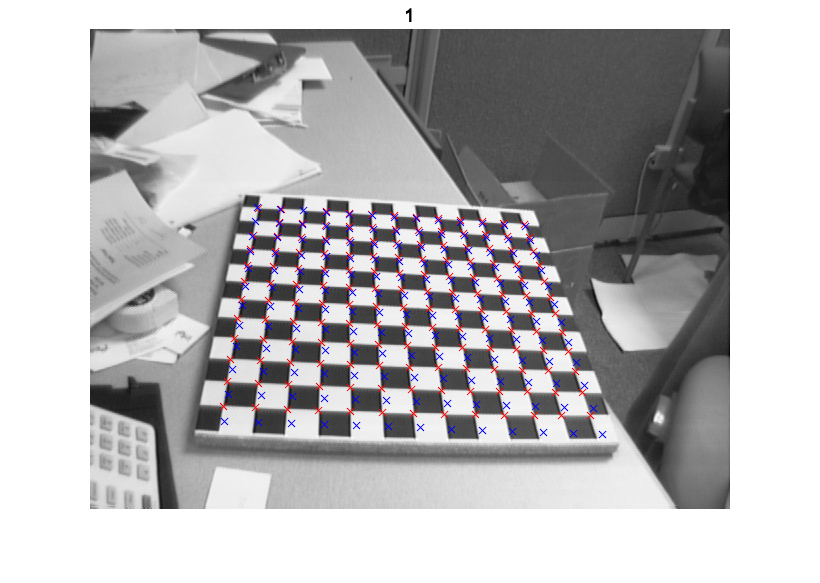

idx = 1; % choose first image
XYpixel = data(idx).XYpixel;
XYmm = data(idx).XYmm;

error = 0; % sum errors

figure
imshow(data(idx).I, 'initialmagnification',200);
title(num2str(idx))
hold on

for i=1:length(XYpixel)

    % coordinates of point in mm
    Xmm=XYmm(i,1); 
    Ymm=XYmm(i,2);
    
    % 3D point m
    m = [Xmm; Ymm; 0; 1];
            
    P = data(idx).P;
    
    estimated_u = (P(1,:)*m)/(P(3,:)*m);
    estimated_v = (P(2,:)*m)/(P(3,:)*m);
    
    % compute the error wrt point visible points on the image
    Xpixel=XYpixel(i,1); 
    Ypixel=XYpixel(i,2); 
    eu = estimated_u - Xpixel; % error on u
    ev = estimated_v - Ypixel; % error on v

    error = error + eu^2 + ev^2;

    scatter(Xpixel,Ypixel, 'x', 'r');
    scatter(estimated_u,estimated_v, 'x', 'b');
end

fprintf("Sum of geomtric errors is: %d", error)

Sum of geomtric errors is: 1.324210e+04

## Superimpose an object

Superimpose a cylinder to the calibration plane, in all the images employed for the calibration and obtain corresponding 2D representation.

The cylinder has center $(x_0, y_0) = (150,150)$, height $h= 150$ and radius  $r = 60$.

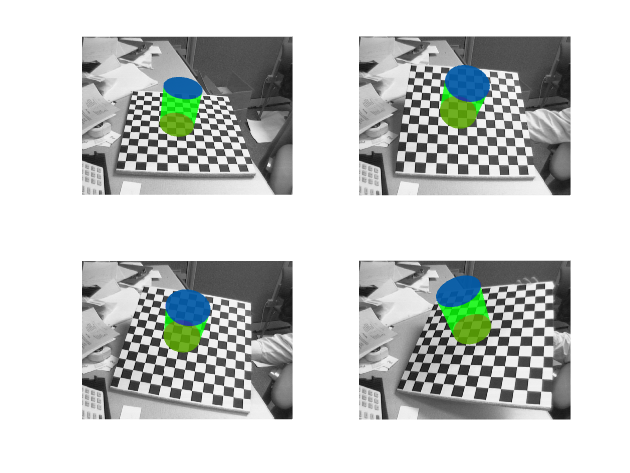

% when considering a 3D shape, we cannot use matrices Hs
% the z coordinates are not zeros and we need then to use full matrix P 

figure

for idx=1:4
    subplot(2,2,idx);
    imshow(data(idx).I)
    hold on
    
    % measures
    d = 120; % diameter
    r = d/2;
    h = 150; % height

    % center
    x0=150;
    y0=150;
   
    
    % points to represent the circles
    n_points = 40;
    angle = pi/n_points;  

    clear m
    % m will contain all the points of the two bases
    m = zeros(n_points*2, 4);
    for i = 1:n_points
        x = x0 + r.*cos(angle + (2*pi/n_points)*i);
        y = y0 + r.*sin(angle + (2*pi/n_points)*i);
        a = [x; y; 0; 1]; % point at the bottom of cylinder
        b = [x; y; h; 1]; % corresponding point at top

        m(i,:) = a; % bottom basis
        m(i+n_points,:) = b; % top basis
    end

    % compute corresponding points in the image reference frame
    projected = zeros(n_points*2, 3);
    for i = 1:length(m)
        res = data(idx).P*m(i,:)';
        if res(3) > 0
            if i > n_points % only for points which have z != 0
                m(i, 3)= -h;
            end
            res = data(idx).P*m(i,:)';
            projected(i,:) = res./res(3);
        else
            projected(i,:) = res./res(3);
        end
    end

    x_bottom = projected(1:n_points,1);
    y_bottom = projected(1:n_points,2);
    x_top = projected(n_points+1:n_points*2,1);
    y_top = projected(n_points+1:n_points*2,2);
    
    % try to show the corpus of cylinder
    % find rightmost and leftmost point
    dist = zeros(n_points/2,1);
    for s=1:n_points/2
        % distances of points at opposite sides (all the possible diameters)
        dist(s) = sqrt((x_bottom(s) - x_bottom(s+n_points/2)).^2 + ...
            (y_bottom(s) - y_bottom(s+n_points/2)).^2); 
    end
    [~, i] = max(dist);
    k = i + n_points/2;

    if (y_bottom(i) > y_top(i) && x_bottom(i) < x_bottom(k) ) || ...
            (y_bottom(i) < y_top(i) && x_bottom(i) > x_bottom(k))
        border_x = [x_bottom(i), x_top(i:k)', x_bottom(k:end)', x_bottom(1:i-1)'];
        border_y = [y_bottom(i), y_top(i:k)', y_bottom(k:end)', y_bottom(1:i-1)'];
        
    else
        border_x = [x_top(i), x_bottom(i:k)', x_top(k:end)', x_top(1:i-1)'];
        border_y = [y_top(i), y_bottom(i:k)', y_top(k:end)', y_top(1:i-1)'];    
    end 

    patch(border_x, border_y,'green', 'LineStyle','none', ...
        'FaceColor', 'green', 'FaceAlpha', 0.8);

    % show basis
    patch(x_bottom, y_bottom, 'red', 'LineStyle','none', ...
        'FaceColor', 'red', 'FaceAlpha', 0.3);
    patch(x_top, y_top,'blue', 'LineStyle','none', ...
        'FaceColor', 'blue', 'FaceAlpha', 0.6);
    
end

Do the same for all the images and save results in 'cylinder_projection' folder.

ImageFolder = strcat(pwd, '\cylinder_projection');
superimposeCylinder(data, ImageFolder);